addpath 'E:\MATLAB'
addpath 'E:'\MATLAB\Images\
%ImageNames={'baby.png';'bird.png';'woman.png';'monarch.png';'airplane.png';'arctichare.png';'peppers1.tiff';'peppers2.png';'foreman.png'};
%ImageNames={'kodim01.png';'kodim02.png';'kodim03.png';'kodim04.png';'kodim05.png';'kodim06.png';'kodim07.png';'kodim08.png';'kodim09.png';'kodim10.png';'kodim11.png';'kodim12.png';'kodim13.png';'kodim14.png';'kodim15.png'};
ImageNames={'aerial1.tiff';'aerial2.tiff';'aerial3.tiff';'aerial4.tiff';'aerial5.tiff';'aerial6.tiff';'aerial7.tiff';'aerial8.tiff';'aerial9.tiff';'aerial10.tiff'};
PSNR_R=zeros(size(ImageNames,1),1);
PSNR_G=zeros(size(ImageNames,1),1);
PSNR_B=zeros(size(ImageNames,1),1);
SSIM_R=zeros(size(ImageNames,1),1);
SSIM_G=zeros(size(ImageNames,1),1);
SSIM_B=zeros(size(ImageNames,1),1);
tic
for i=1:size(ImageNames,1)
    string=char(ImageNames(i));
    A=(imread(string));
    AA=rgb2gray(A);
    AAA=KipkoechDownSampling1(double(AA),2);
    AAAA=imresize(AAA,2);
    R = double(A(:,:,1)); % Red channel
    G = double(A(:,:,2)); % Green channel
    B = double(A(:,:,3)); % Blue channel
    SR31=KipkoechDownSampling1(R,2);
    SR3=imresize(SR31,2,'bicubic');
    SR32=KipkoechDownSampling1(G,2);
    SR3G=imresize(SR32,2,'bicubic');
    SR33=KipkoechDownSampling1(B,2);
    SR3B=imresize(SR33,2,'bicubic');
    PSNR_R(i)=psnr(uint8(SR3),uint8(R));
    PSNR_G(i)=psnr(uint8(SR3G),uint8(G));
    PSNR_B(i)=psnr(uint8(SR3B),uint8(B));
    SSIM_R(i)=ssim(uint8(SR3),uint8(R));
    SSIM_G(i)=ssim(uint8(SR3G),uint8(G));
    SSIM_B(i)=ssim(uint8(SR3B),uint8(B));
    SRimagee=cat(3,SR3,SR3G,SR3B);
    %imwrite(uint8(SRimagee),'E:\MATLAB\IMAGE SETS\SR_testing_datasets\results\zebrabicubic.png')
%     imwrite(uint8(SRimagee),'lenabicubic.png')
    %imshow(uint8(SRimagee))
end
toc

Elapsed time is 5.530922 seconds.


T=table(ImageNames,PSNR_R,PSNR_G,PSNR_B,SSIM_R,SSIM_G,SSIM_B)

T = 10×7 table
       ImageNames        PSNR_R    PSNR_G    PSNR_B    SSIM_R     SSIM_G     SSIM_B 
    _________________    ______    ______    ______    _______    _______    _______

    {'aerial1.tiff' }    30.453    33.722    39.174    0.76522    0.83476    0.91015
    {'aerial2.tiff' }    31.998    35.137    38.965    0.84937    0.86502    0.90328
    {'aerial3.tiff' }    27.447    28.823    35.477    0.79997    0.77972    0.85061
    {'aerial4.tiff' }     28.39    29.186     30.79    0.83836    0.81925    0.75616
    {'aerial5.tiff' }    33.629    34.115    34.565    0.78781    0.78951    0.77122
    {'aerial6.tiff' }    31.703    32.917    36.139    0.80728    0.80291    0.83272
    {'aerial7.tiff' }    27.827    31.734    39.347    0.78742    

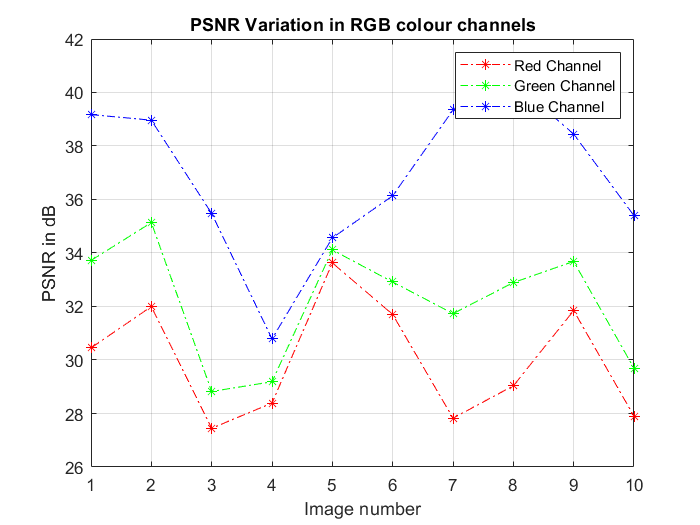

Table_location='E:\MATLAB\Results';
path_format = [Table_location '\BICUBIcset14Factor2.xlsx'];
writetable(T,path_format)
writetable(T,path_format)
n=1:size(ImageNames,1);
figure;
plot(n,PSNR_R,'-.r*',n,PSNR_G,'-.g*',n,PSNR_B,'-.b*')
grid on
ylabel ('PSNR in dB')
xlabel ('Image number')
title ('PSNR Variation in RGB colour channels','FontWeight','bold');
legend('Red Channel','Green Channel','Blue Channel')

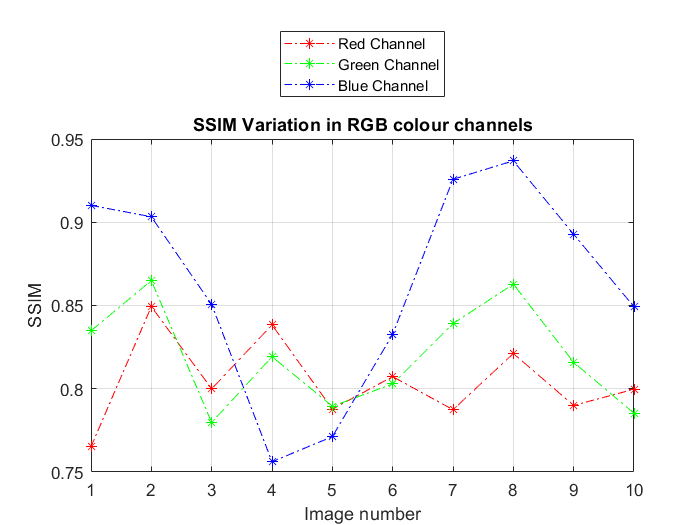

figure;
plot(n,SSIM_R,'-.r*',n,SSIM_G,'-.g*',n,SSIM_B,'-.b*')
grid on
ylabel ('SSIM')
xlabel ('Image number')
title ('SSIM Variation in RGB colour channels','FontWeight','bold');
legend('Red Channel','Green Channel','Blue Channel', ...
    'Location','northoutside')